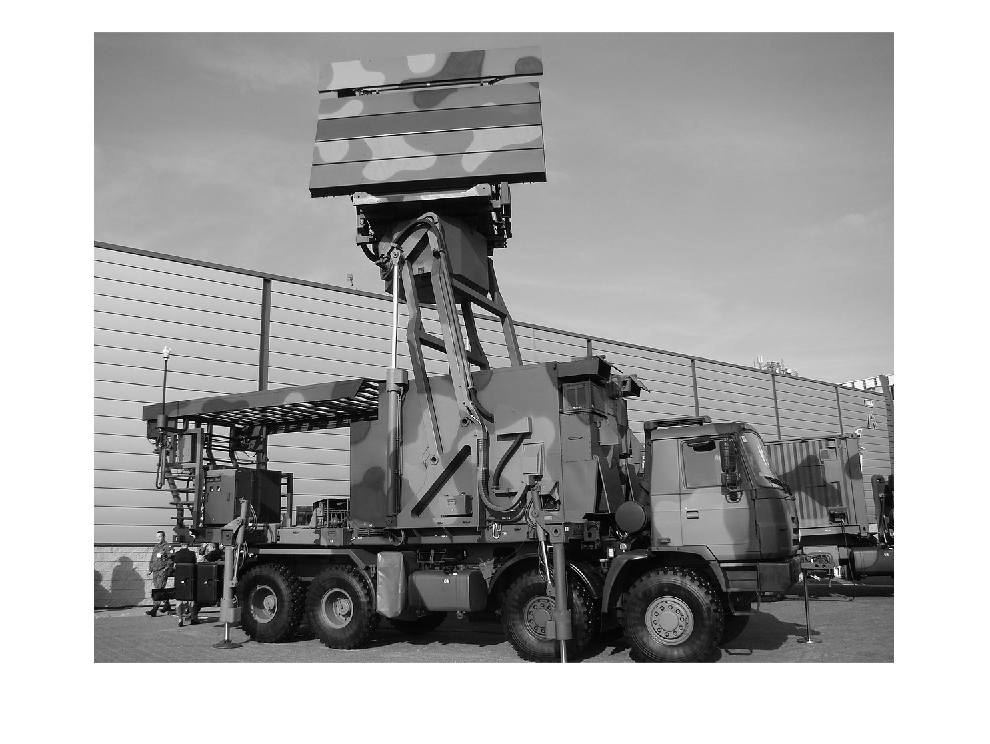

%Script to recognize radars

clc
clear

%Obraz źródłowy
image = imread('nur15.jpg');
% image = imresize(image, 0.2);
% image = imrotate(image, -90); %Obót obrazu o 90*, jeśli potrzeba
%Wyświetlenie obrazu
image = RGBToGray(image); %zamiana na obraz monochromatyczny
imshow(image); 

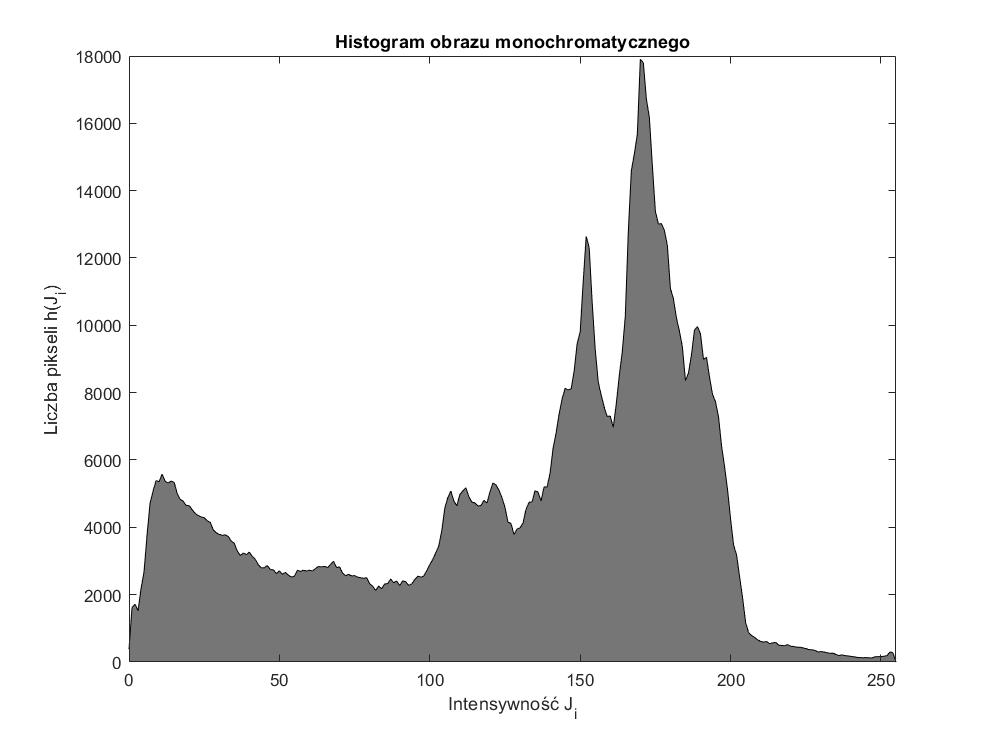


%Wyświetlenie histogramu
showhistogram(image, -1);

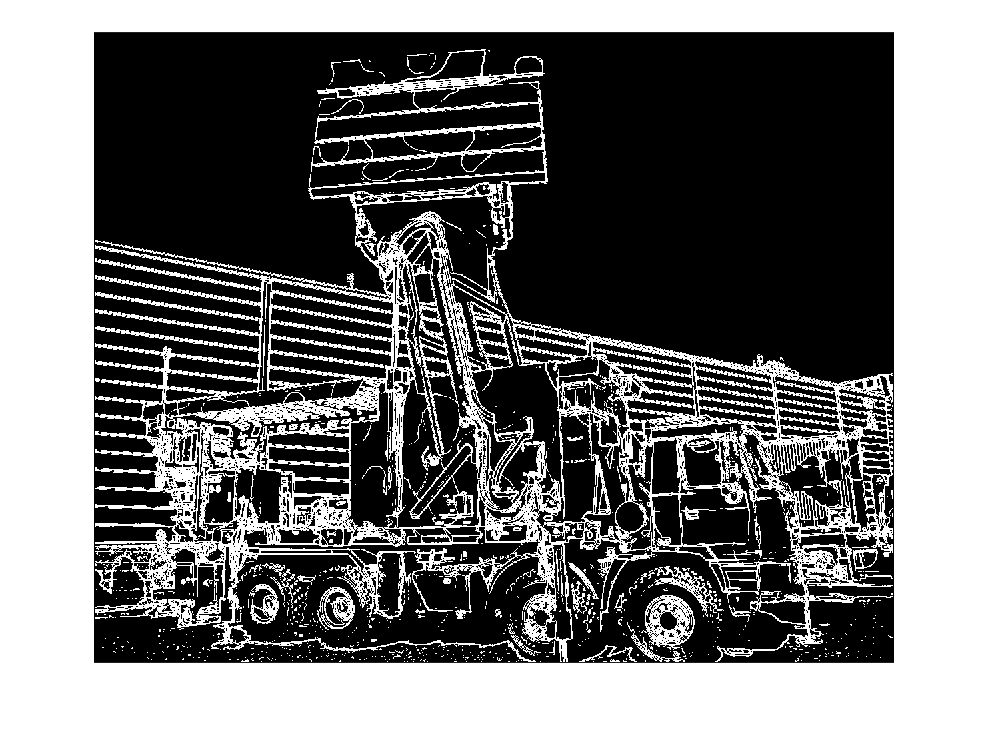


%Detekcja krawędzi metodą Sobela
%Progowanie t z zakresu [0;255]. Jeśli t < 0 - bez progowania
t = 20;
[sobel_img, beforeThresh] = sobel_detector(image, t);
imshow(sobel_img);

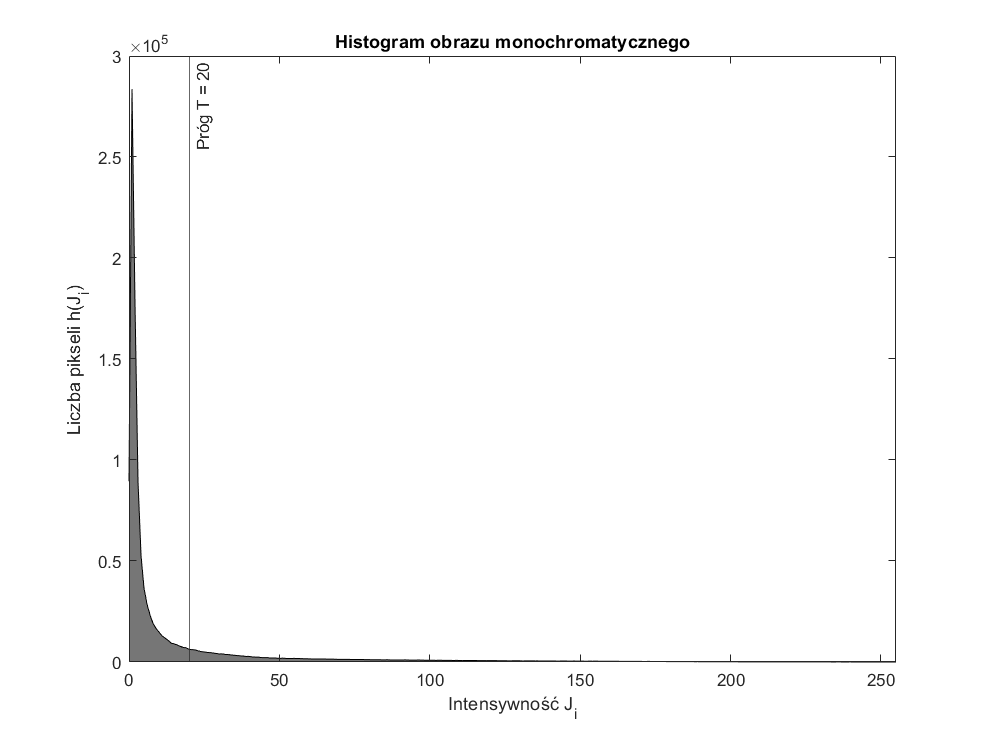

showhistogram(beforeThresh, t);

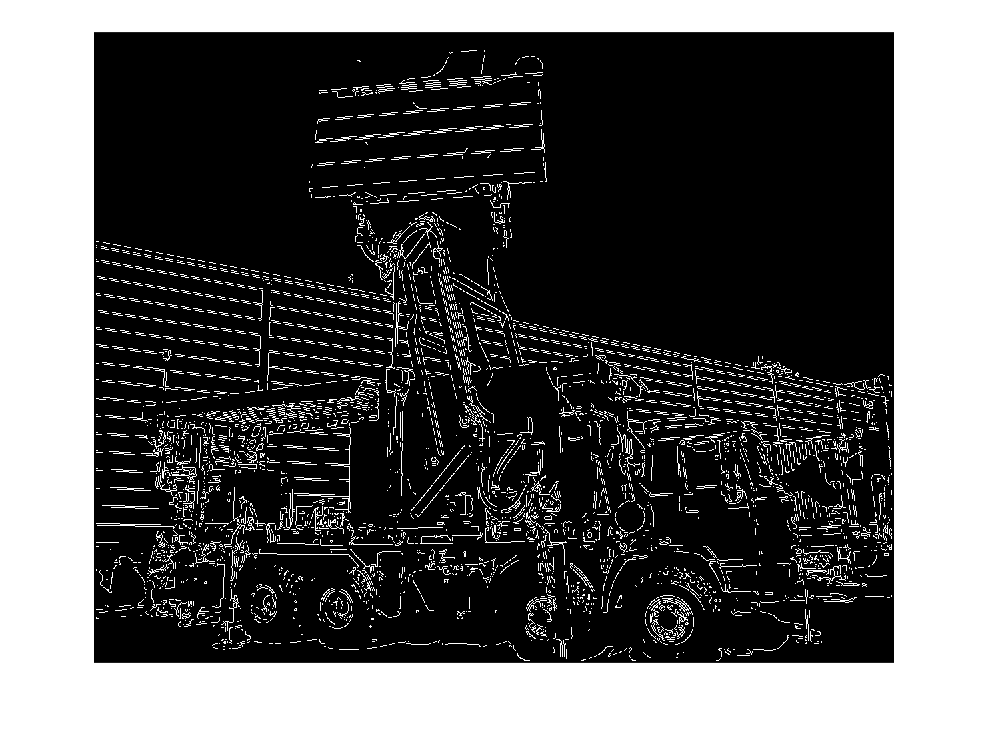


%Detekcja krawędzi metodą Cannyego
%TLow - dolna granica progowania
%THigh - górna granica progowania
% TLow < THigh i z zakresu 0 do 255
%Sigma i kernelSize są parametrami filtra wygładzającego gasusaa. Im
%większe wartości, tym obraz będzie wstępnie bardziej wygładzony.
TLow = 19;
THigh = 44;
sigma = 1.5;
kernelSize = 3;
[canny_img, cannyNMS] = canny_detector(image, TLow, THigh, sigma, kernelSize);
imshow(canny_img);

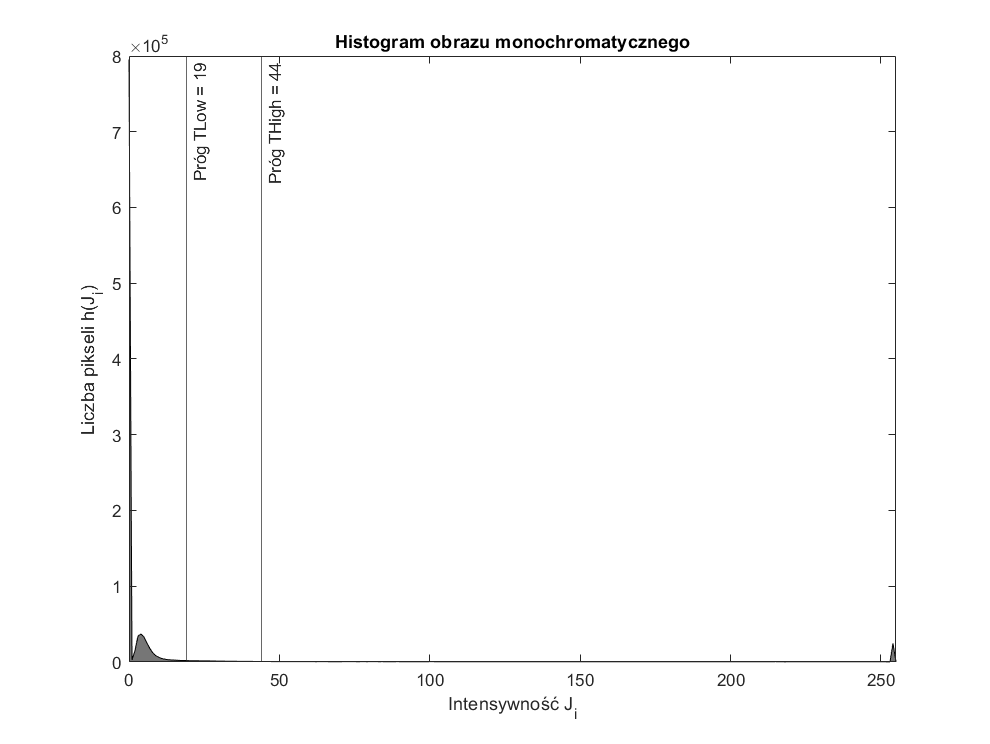

showhistogramCanny(cannyNMS, TLow, THigh);